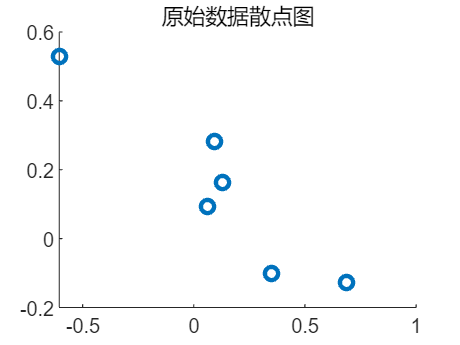

clc; clear;
load k1secs.mat
data = k1sec2';
% data(:,1)=[90,35,52,83,64,24,49,92,99,45,19,38,1,71,56,97,63,...
%     32,3,34,33,55,75,84,53,15,88,66,41,51,39,78,67,65,25,40,77,...
%     13,69,29,14,54,87,47,44,58,8,68,81,31];
% data(:,2)=[33,71,62,34,49,48,46,69,56,59,28,14,55,41,39,...
%     78,23,99,68,30,87,85,43,88,2,47,50,77,22,76,94,11,80,...
%     51,6,7,72,36,90,96,44,61,70,60,75,74,63,40,81,4];
figure(1)
scatter(data(:,1),data(:,2),'LineWidth',2)
title("原始数据散点图")

cluster_num=6;
[index_cluster,cluster] = kmeans_func(data,cluster_num);

无法执行赋值，因为左侧的大小为 1×1，右侧的大小为 1×34。

出错 kmeans_func (第 18 行)
        cluster_new(j,:)=mean(data(find(index_cluster==j),:));

%% 画出聚类效果
figure(2)
% subplot(2,1,1)
a=unique(index_cluster); %找出分类出的个数
C=cell(1,length(a));
for i=1:length(a)
   C(1,i)={find(index_cluster==a(i))};
end
for j=1:cluster_num
    data_get=data(C{1,j},:);
    scatter(data_get(:,1),data_get(:,2),100,'filled','MarkerFaceAlpha',.6,'MarkerEdgeAlpha',.9);
    hold on
end
%绘制聚类中心
plot(cluster(:,1),cluster(:,2),'ks','LineWidth',2);
hold on
sc_t=mean(silhouette(data,index_cluster'));
title_str=['原理推导K均值聚类','  聚类数为：',num2str(cluster_num),'  SC轮廓系数:',num2str(sc_t)];
title(title_str)